a=[1 2 3;3 4 5]

a =      1     2     3
     3     4     5


b =      1     2     3     4
     2     3     3     4


[r c]=size(a)

r = 2

c = 3

ndims(a)

ans = 2

age=4

age = 4

fprintf('my age is %d. my name is.. ',4)

my age is 4. my name is.. 

Listing 1



x=[1 2 3; 5 6 7; 4 5 6]

x =      1     2     3
     5     6     7
     4     5     6


N=3

N = 3

[r, c] = size(x);
if (r ~= 3) || (c ~= N) || (ndims(x) ~= 2)
error(sprintf( ['functionname : input vector x needs to be a ' ...
    'row vector of length N (N = % d) . . . '],N));
end

x*3

ans =      3     6     9
    15    18    21
    12    15    18


2.2.1 Generation of the bit sequences

randBits=generateBits(50)

randBits =    -1.0933   -0.4336   -0.1685   -0.2185    0.5413    0.3893    0.7512    1.7783    1.2231   -1.2833   -2.3290    0.9019   -1.8356    0.0668    0.0355    2.2272   -0.0692   -0.5073    0.2358    0.2458    0.0700   -0.6086   -1.2226    0.3165   -1.3429   -1.0322    1.3312   -0.4189   -0.1403    0.8998   -0.3001    1.0294   -0.3451    1.0128    0.6293   -0.2130   -0.8657   -1.0431   -0.2701   -0.4381   -0.4087    0.9835   -0.2977    1.1437   -0.5316    0.9726   -0.5223    0.1766    0.9707   -0.4140


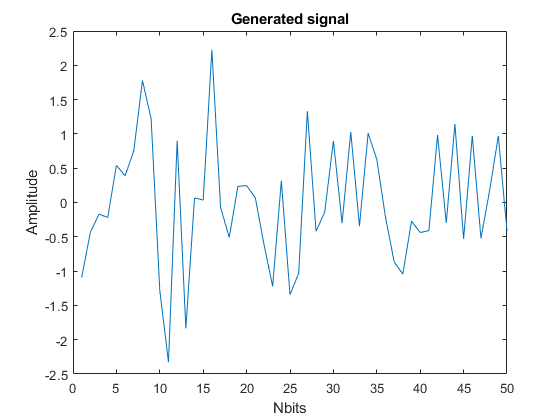

plot(randBits)
xlabel("Nbits")
ylabel("Amplitude")

Listing 2: Example of a simulation script

SNR=1:10;
%Modulationformat=QPSK
error=0
nBits=50
for i=SNR
    while error<100
        randBits=generateBits(Nbits)
        plot(randBits)
        xlabel("Nbits")
        ylabel("Amplitude")
        title("Generation of the bit sequences")
    end
    
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

Listing 3:Beginning of theactual simulation script

clc; clear variables; % clear all variables
addpath( 'subfunctions'); % add directory "subfunctions" to path
% global simulation parameters
ebN0dB = 0:30; % SNR (per bit) in dB
nBitsPerLoop = 10e3; % simulate nBitsPerLoop bits per simlation loop
nMinErr = 100; % simulate at least nMinErr bit errors...
nMaxBits = 100 * nBitsPerLoop; % ... or stop after nMaxBits
const = [-1-1j, 1-1j, -1+1j, 1+1j]; % constellation of the
% modulation format here: QPSK wiht Gray mapping)
% here goes the simulation loop...

# Listing 3  

Table 1


decimal=[0:3]'

decimal =      0
     1
     2
     3



binary=dec2bin(decimal)

binary = 4×2 char array
    '00'
    '01'
    '10'
    '11'




index=(1:length(decimal))'

index =      1
     2
     3
     4


const = [-1-1j, 1-1j, -1+1j, 1+1j].'

const =   -1.0000 - 1.0000i
   1.0000 - 1.0000i
  -1.0000 + 1.0000i
   1.0000 + 1.0000i


T=table(binary,decimal,index,const)

T = 4×4 table
    binary    decimal    index    const
    ______    _______    _____    _____

      00         0         1      -1-1i
      01         1         2       1-1i
      10         2         3      -1+1i
      11         3         4       1+1i


generateBits(23)

ans =     0.5377    1.8339   -2.2588    0.8622    0.3188   -1.3077   -0.4336    0.3426    3.5784    2.7694   -1.3499    3.0349    0.7254   -0.0631    0.7147   -0.2050   -0.1241    1.4897    1.4090    1.4172    0.6715   -1.2075    0.7172


function y=mapper(bits,const)
    

end

function y=generateBits(nBits)
    y=randn(1,nBits);
end



